Function

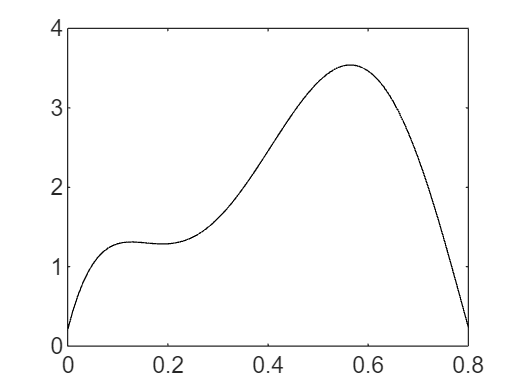

%format long
format short

f=@(x) 400.*x.^5 - 900.*x.^4 + 675.*x.^3 - 200.*x.^2 + 25.*x + 0.2;

xx = 0 : 0.01 : 0.8;
yy = f(xx);
plot(xx,yy,'k-')

To integrate function from 0 to 0.8

Plot original function along with simpson 1/3 rule with ns calculated from adaptive quadrature

a = 0

a = 0

b = 0.8

b = 0.8000


[I_quadadapt, xpts] = quadadapt_with_pts(f,a,b);

I_quadadapt

I_quadadapt = 1.6405


ypts = f(xpts);

[xpts ypts]

ans =          0    0.2000
    0.0063    0.3486
    0.0125    0.4825
    0.0188    0.6028
    0.0250    0.7102
    0.0312    0.8057
    0.0375    0.8901
    0.0438    0.9642
    0.0500    1.0289
    0.0563    1.0848



ns = (length(xpts)-1)/2

ns = 46

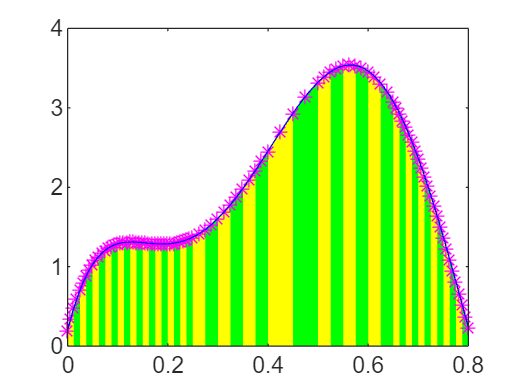


figure
color = ['g','y'];
for i = 1:ns
    il = 2*(i-1)+1;
    ir = 2*i+1;
    newx = xpts(il:ir);
    newy = ypts(il:ir);
    p2 = polyfit(newx,newy,2);
    xx2 = linspace(xpts(il),xpts(ir));
    yy2 = polyval(p2,xx2);

    area(xx2,yy2,'FaceColor',color(mod(i,2)+1) ,'EdgeColor','black','LineStyle','-')
    hold on
    plot(xpts(il:ir),ypts(il:ir),'m*')
end
plot(xx,yy,'b-')